# ISAC topology framework 

# Select topology BEFORE running for reproducibility.

clear cfg
%cfg.scenarioName = "baseline";
%cfg.scenarioName = "openArea";
cfg.scenarioName = "piotrkowskaStreetCanyon";
cfg.topology = "bistatic"; % "monostatic" | "bistatic"
% Target trajectory case.
% Options for piotrkowskaStreetCanyon:
% "singleT1Fast"
% "singleT1Slow"
% "singleT2Slow"
 "twoTargetsOriginalFast"

ans = "twoTargetsOriginalFast"

 %"twoTargetsOriginalSlow"
% "twoTargetsSeparatedSlow"
cfg.targetCase = "twoTargetsOriginalFast";
cfg.showResourceGrid = true;
cfg.printSensingLimits = true;
cfg.printMetricsSummary = true; 

cfg.debugGeometry = false;      % Print true range/AoA/AoD per target and frame
cfg.cfarPfa = 1e-5;            % Debug value. Later return to 1e-5
cfg.osmReflectionScale = 1.0;  % Keep 1.0 first. Try 0.2 only if geometry is OK% Print a short summary of the basic comparison metrics

rng('default');                                            % Set the random number generator for reproducibility
carrierFrequency = 30e9;                                   % Carrier frequency (Hz)
wavelength = freq2wavelen(carrierFrequency);

Transmitter and receiver location.

%% Scenario-dependent geometry

scenarioConfig = helperGetScenarioConfig(cfg.scenarioName, cfg.topology);

txPosition = scenarioConfig.txPosition;
rxPosition = scenarioConfig.rxPosition;
regionOfInterest = scenarioConfig.roi;

fprintf("Selected scenario: %s\n", cfg.scenarioName);

Selected scenario: piotrkowskaStreetCanyon


fprintf("Selected topology: %s\n", cfg.topology);

Selected topology: bistatic


fprintf("Tx position: [%.1f %.1f %.1f] m\n", txPosition);

Tx position: [-10.0 -40.0 0.0] m


fprintf("Rx position: [%.1f %.1f %.1f] m\n", rxPosition);

Rx position: [-20.0 40.0 0.0] m


%% Scenario plot limits

plotMargin = 10; % meters

scenarioPlotXLim = [scenarioConfig.roi(1,1)-plotMargin, ...
                    scenarioConfig.roi(1,2)+plotMargin];

scenarioPlotYLim = [scenarioConfig.roi(2,1)-plotMargin, ...
                    scenarioConfig.roi(2,2)+plotMargin];

Creation of transmitter and reciever 

txPower = 46;                                              % dBm
transmitter = phased.Transmitter('PeakPower', db2pow(txPower-30), 'Gain', 0);

numTxAntennas = 8;                                         % Number of antenna elements at the Tx array
element = phased.IsotropicAntennaElement('BackBaffled', true);
txArray = phased.ULA(numTxAntennas, wavelength/2, 'Element', element);
txOrientationAxes = scenarioConfig.txOrientationAxes;% Tx array orientation

receiver = phased.Receiver('AddInputNoise', true, 'Gain', 0, 'NoiseMethod', 'Noise figure',...
    'NoiseFigure', 5, 'ReferenceTemperature', 290);

% Topology-dependent Rx array and orientation
switch cfg.topology
    case "bistatic"
        numRxAntennas = 8;
        rxArray = phased.ULA(numRxAntennas, wavelength/2, 'Element', element);
        rxOrientationAxes = scenarioConfig.rxOrientationAxes;

    case "monostatic"
        numRxAntennas = numTxAntennas;
        rxArray = txArray;
        rxOrientationAxes = scenarioConfig.rxOrientationAxes;
end

Scatterers 

%% Scenario-dependent static scatterers

if scenarioConfig.useOSMScatterers

    if ~isfile(scenarioConfig.scattererMatFile)
        error("OSM scatterer file not found: %s", scenarioConfig.scattererMatFile);
    end

    data = load(scenarioConfig.scattererMatFile, ...
        "scattererPositions", ...
        "reflectionCoefficients");

    scatterers.Positions = data.scattererPositions;
    scatterers.ReflectionCoefficients = data.reflectionCoefficients;

else

    numScatterers = 40;

    [scatterers.Positions, scatterers.ReflectionCoefficients] = ...
        helperGenerateStaticScatterers(numScatterers, regionOfInterest);

end

scatterers.Velocities = zeros(size(scatterers.Positions));

fprintf("Number of static scatterers: %d\n", size(scatterers.Positions, 2));

Number of static scatterers: 573



targets.Trajectories = helperGetTargetTrajectories(cfg.scenarioName, cfg.targetCase);
numTargets = numel(targets.Trajectories);
targets.ReflectionCoefficients = exp(1i*(2*pi*rand(1, numTargets)));

Channel

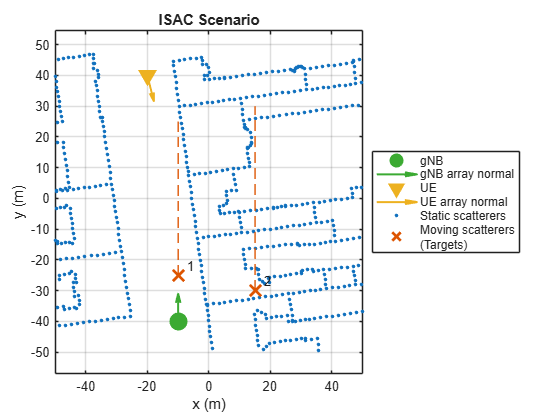

% Topology-dependent direct path
simulateDirectPath = cfg.topology == "bistatic";
channel = phased.ScatteringMIMOChannel('CarrierFrequency', carrierFrequency, 'TransmitArray', txArray,...
    'TransmitArrayPosition', txPosition, 'ReceiveArray', rxArray, 'ReceiveArrayPosition', rxPosition,...
    "TransmitArrayOrientationAxes", txOrientationAxes, "ReceiveArrayOrientationAxes", rxOrientationAxes,...
    'SimulateDirectPath', simulateDirectPath, 'ScattererSpecificationSource', 'Input Port', ...
    'ChannelResponseOutputPort',true,'Polarization','None');

helperVisualizeScatteringMIMOChannel(channel, scatterers.Positions, targets.Trajectories);
title('ISAC Scenario');

**5G Waveform Configuration**

channelBandwidth = 50;
bandwidthOccupancy = 0.9;
subcarrierSpacing = 60;

waveformConfig = helperGet5GWaveformConfiguration(channelBandwidth, bandwidthOccupancy, subcarrierSpacing);
waveformInfo = nrOFDMInfo(waveformConfig.Carrier);

transmissionBandwidth = subcarrierSpacing*1e3*waveformConfig.Carrier.NSizeGrid*12;
if cfg.printSensingLimits
    fprintf("Transmission bandwidth: %.2f MHz\n",transmissionBandwidth*1e-6);
end

Transmission bandwidth: 44.64 MHz



channel.SampleRate = waveformInfo.SampleRate;

**DM-RS parameters.**

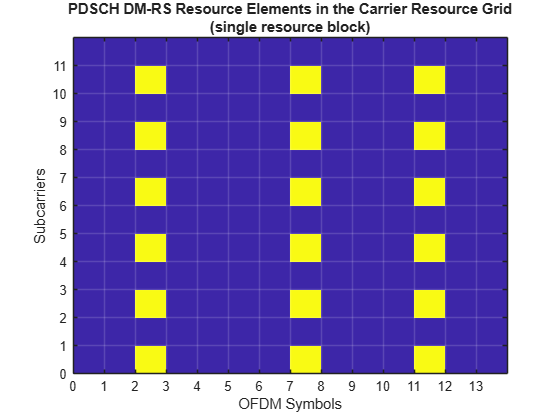

waveformConfig.PDSCH.DMRS.DMRSTypeAPosition = 2;
waveformConfig.PDSCH.DMRS.DMRSLength = 1;
waveformConfig.PDSCH.DMRS.DMRSAdditionalPosition = 2;
waveformConfig.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;
waveformConfig.PDSCH.DMRS.DMRSConfigurationType = 1;
if cfg.showResourceGrid
    resourceGrid = nrResourceGrid(waveformConfig.Carrier, waveformConfig.PDSCH.NumLayers);
    ind = nrPDSCHDMRSIndices(waveformConfig.Carrier, waveformConfig.PDSCH);
    resourceGrid(ind) = nrPDSCHDMRS(waveformConfig.Carrier, waveformConfig.PDSCH);
    helperVisualizeResourceGrid(abs(resourceGrid(1:12,1:14,1)));
    title({'PDSCH DM-RS Resource Elements in the Carrier Resource Grid', '(single resource block)'});
end

Doppler

% Literal computations from original scripts
[~,pdschInfo] = nrPDSCHIndices(waveformConfig.Carrier,waveformConfig.PDSCH);
Mt = max(diff(pdschInfo.DMRSSymbolSet));
ofdmSymbolDuration = max(waveformInfo.SymbolLengths)/waveformInfo.SampleRate;
maxDoppler = 1/(2*Mt*ofdmSymbolDuration);

Velocity

maxVelocity = dop2speed(maxDoppler, wavelength);
if cfg.topology == "monostatic"
    maxVelocity = maxVelocity/2;
end

Delay

Mf = min(diff(waveformConfig.PDSCH.DMRS.DMRSSubcarrierLocations));
maxDelay = 1/(2*Mf*subcarrierSpacing*1e3);
channel.MaximumDelaySource = 'Property';
channel.MaximumDelay = maxDelay;

Range 

propagationSpeed = physconst("LightSpeed");
if cfg.topology == "bistatic"
    baseline = vecnorm(txPosition-rxPosition);
    maxRange = maxDelay*propagationSpeed-baseline;
else
    baseline = 0;
    maxRange = maxDelay*propagationSpeed/2;
end
rangeResolution = propagationSpeed/transmissionBandwidth;
if cfg.printSensingLimits

    
    fprintf('Maximum unambiguous Doppler shift: %.2f kHz\n', maxDoppler*1e-3);
    fprintf('Maximum unambiguous velocity: %.2f m/s\n', maxVelocity);
    fprintf('Maximum time delay: %.2fe-6 s\n', maxDelay*1e6);
    fprintf('Maximum unambiguous %s range: %.2f m\n', cfg.topology, maxRange);
    fprintf('Range resolution: %.2f m\n', rangeResolution);
end

Maximum unambiguous Doppler shift: 5.45 kHz


Maximum unambiguous velocity: 54.43 m/s


Maximum time delay: 4.17e-6 s


Maximum unambiguous bistatic range: 1168.51 m


Range resolution: 6.72 m


**Channel Simulation and Sensing Data Processing**

dt = 0.4;

% Use longer simulations for slow Piotrkowska target cases.
numSensingFrames = 10;

if isfield(cfg, "targetCase") && contains(cfg.targetCase, "Slow")
    numSensingFrames = 20;
end

t = (0:numSensingFrames-1)*dt;

numAoA = ceil(2*pi*numRxAntennas);
aoaGrid = linspace(-90, 90, numAoA);
rxSteeringVector = phased.SteeringVector(SensorArray=channel.ReceiveArray);
rxsv = rxSteeringVector(carrierFrequency, aoaGrid);

numAoD = ceil(2*pi*numTxAntennas);
aodGrid = linspace(-90, 90, numAoD);
txSteeringVector = phased.SteeringVector(SensorArray=channel.TransmitArray);
txsv = txSteeringVector(carrierFrequency, aodGrid);
% Topology-dependen
if cfg.topology == "bistatic"
    rangeGrid = -20:rangeResolution/4:100;
    rangeFFTBins = (rangeGrid + baseline)/rangeResolution;
else
    rangeGrid = 0:rangeResolution/4:100;
    rangeFFTBins = (2*rangeGrid)/rangeResolution;
end
numRange = numel(rangeGrid);
numSubcarriers = waveformConfig.Carrier.NSizeGrid*12;
k = (0:numSubcarriers-1).';
rngsv = (exp(2*pi*1i*k*rangeFFTBins/numSubcarriers)/numSubcarriers);

2-D CFAR detector

numGuardCellsRange = ceil(rangeResolution/(rangeGrid(2)-rangeGrid(1))) + 1;
aoaResolution = ap2beamwidth((numRxAntennas-1)*channel.ReceiveArray.ElementSpacing, wavelength);
numGuardCellsAoA = ceil(aoaResolution/(aoaGrid(2)-aoaGrid(1))) + 1;
cfar2D = phased.CFARDetector2D( ...
    'GuardBandSize', [numGuardCellsRange numGuardCellsAoA], ...
    'TrainingBandSize', [4 6], ...
    'ProbabilityFalseAlarm', cfg.cfarPfa, ...
    'OutputFormat', 'CUT result', ...
    'ThresholdOutputPort', false);
offsetIdxs = cfar2D.TrainingBandSize + cfar2D.GuardBandSize;
rangeIdxs = offsetIdxs(1)+1:numel(rangeGrid)-offsetIdxs(1);
angleIdxs = offsetIdxs(2)+1:numel(aoaGrid)-offsetIdxs(2);
[sumRangeIdxs, aoaIdxs] = meshgrid(rangeIdxs, angleIdxs);
cutidx = [sumRangeIdxs(:).'; aoaIdxs(:).'];

clusterer = clusterDBSCAN();

Tracker

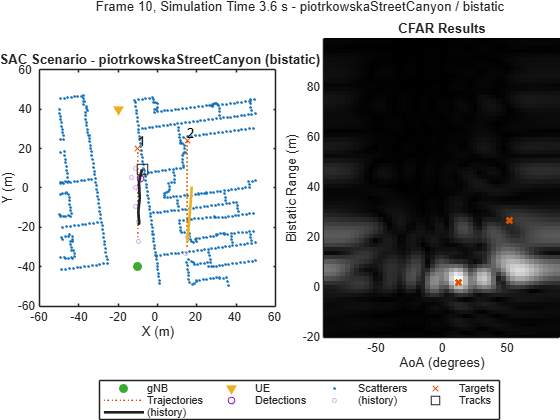


Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 1 | Truth separation: dRange = 24.42 m | dAoA = 17.82 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 2 | Truth separation: dRange = 21.80 m | dAoA = 19.21 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 3 | Truth separation: dRange = 20.14 m | dAoA = 20.80 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 4 | Truth separation: dRange = 19.23 m | dAoA = 22.63 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 5 | Truth separation: dRange = 18.91 m | dAoA = 24.74 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 6 | Truth separation: dRange = 19.09 m | dAoA = 27.15 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 7 | Truth separation: dRange = 19.75 m | dAoA = 29.88 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 8 | Truth separation: dRange = 20.90 m | dAoA = 32.91 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 9 | Truth separation: dRange = 22.57 m | dAoA = 36.05 deg



Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


Frame 10 | Truth separation: dRange = 24.83 m | dAoA = 38.87 deg


tracker = helperConfigureTrackerByTopology(cfg.topology, txPosition, rxPosition, txOrientationAxes, rxOrientationAxes, rangeResolution, aoaResolution);
targetStateEstimates = zeros(4, numSensingFrames, 10);
trackIDs = [];
% Number of clustered CFAR detections per frame.
% This metric indicates how many final sensing detections are produced after CFAR and DBSCAN.
% It helps compare whether one topology generates more false or duplicated detections.
numDetectionsPerFrame = zeros(numSensingFrames, 1);

% Number of raw CFAR detections per frame before DBSCAN clustering.
% This metric counts how many range-AoA cells are declared as detections by CFAR.
% It helps distinguish raw detector sensitivity from clustered detections and confirmed tracks.
numRawCFARDetectionsPerFrame = zeros(numSensingFrames, 1);

% Number of active tracks per frame.
% This metric helps evaluate whether the tracker follows the expected number of moving targets
% or creates/lost tracks depending on the topology.
numTracksPerFrame = zeros(numSensingFrames, 1);

% Approximate number of extra tracks per frame.
% This first-order metric flags cases where the tracker creates more tracks than the number of real moving targets.
falseTracksPerFrame = zeros(numSensingFrames, 1);

% Truth association metric storage.
% Each cell stores the real target positions in the range-AoA map:
% [trueRange; trueAoA]
truthRangeAoAPerFrame = cell(numSensingFrames, 1);

% Each cell stores clustered CFAR detections:
% [detectedRange; detectedAoA]
clusteredDetectionsPerFrame = cell(numSensingFrames, 1);

% Per-frame truth hit rate.
truthHitRatePerFrame = zeros(numSensingFrames, 1);
% Per-target truth association matrix.

% Rows = frames, columns = targets.
% targetHitMatrix(i,it) = true if target it has at least one clustered detection
% close to its true [range; AoA] point in frame i.
targetHitMatrix = false(numSensingFrames, numTargets);

% Tracking-level metric storage.
% This evaluates whether the tracker estimate is close to the real target
% position in Cartesian coordinates, independently of whether the current
% CFAR detection is close to the target.
trackPositionErrorPerFrame = NaN(numSensingFrames, numTargets);
trackHitMatrix = false(numSensingFrames, numTargets);

% Maximum Cartesian distance for considering that a track is close to a target.
trackDistanceTolerance = 8; % meter
% Temporal alignment diagnostic.
% Stores true target positions for each frame and compares the tracker output
% against the previous-frame ground truth. This helps identify whether the
% tracker is following the target with a one-frame delay.
targetPositionsHistory = NaN(numSensingFrames, numTargets, 3);

trackPositionErrorPrevTruthPerFrame = NaN(numSensingFrames, numTargets);
trackHitPrevTruthMatrix = false(numSensingFrames, numTargets);
% Tolerances for deciding whether a clustered detection is close to the truth.
truthRangeTolerance = 8;   % meters
truthAoATolerance = 10;    % degrees
% Range-AoA separation diagnostic between two targets.
% This helps determine whether two targets become difficult to separate
% in the sensing map.
truthRangeSeparationPerFrame = NaN(numSensingFrames, 1);
truthAoASeparationPerFrame = NaN(numSensingFrames, 1);
%%
generateVisualizations = true;
if generateVisualizations
    scenarioCFARResultsFigure = figure;
    tl = tiledlayout(scenarioCFARResultsFigure, 1, 2, ...
        'Padding', 'tight', ...
        'TileSpacing', 'tight');

    scenarioPlotter = helperTheaterPlotter(tl);
   
    scenarioPlotter.plotTxAndRx(txPosition, rxPosition);
    scenarioPlotter.plotTrajectories(targets.Trajectories, t);
    scenarioPlotter.plotScatterers(scatterers.Positions);

       title(scenarioPlotter, ...
        sprintf('ISAC Scenario - %s (%s)', cfg.scenarioName, cfg.topology));

    % Force Cartesian scenario plot limits according to selected scenario ROI.
    % scenarioPlotter is a helper object, so we modify the actual axes.
    scenarioAxes = findobj(scenarioCFARResultsFigure, 'Type', 'Axes');

    % At this point, before creating the CFAR visualizer, the scenario axes
    % should be the only axes in the figure.
    set(scenarioAxes(1), ...
        'XLim', scenarioPlotXLim, ...
        'YLim', scenarioPlotYLim);

    cfarResultsVisualizer = helperCFARResultsVisualizer(tl);
    xlabel(cfarResultsVisualizer, 'AoA (degrees)');

    if cfg.topology == "bistatic"
        ylabel(cfarResultsVisualizer, 'Bistatic Range (m)');
    else
        ylabel(cfarResultsVisualizer, 'Monostatic Range (m)');
    end

    title(cfarResultsVisualizer, 'CFAR Results');

    
end
numSymbolsPerFrame = waveformInfo.SlotsPerFrame*waveformInfo.SymbolsPerSlot;

for i = 1:numSensingFrames
    
    sensingCSI = helperSimulateLinkSingleFrame(transmitter, receiver, channel, waveformConfig, scatterers, targets, t(i));
    reset(channel);
    % True target positions for this frame
    targetPositions = zeros(numTargets, 3);
    for it = 1:numTargets
        targetPositions(it, :) = lookupPose(targets.Trajectories{it}, t(i));
    end
    % Store true target positions for temporal-alignment diagnostics.
    targetPositionsHistory(i, :, :) = targetPositions;
   % True range, AoA and AoD with current orientations
[trueRrx, trueAoA] = rangeangle(targetPositions.', rxPosition, rxOrientationAxes);
[trueRtx, trueAoD] = rangeangle(targetPositions.', txPosition, txOrientationAxes);

if cfg.topology == "bistatic"
    trueRange = trueRrx + trueRtx - baseline;
else
    trueRange = trueRrx;
end

% Store ground truth in the same range-AoA domain used by the CFAR map.
% Format: 2 x numTargets -> [trueRange; trueAoA]
truthRangeAoAPerFrame{i} = [trueRange(:).'; trueAoA(1, :)];
% Store range-AoA separation between the two true targets.
if numTargets == 2
    truthRangeSeparationPerFrame(i) = abs(trueRange(1) - trueRange(2));
    truthAoASeparationPerFrame(i) = abs(wrapTo180(trueAoA(1,1) - trueAoA(1,2)));

    fprintf("Frame %d | Truth separation: dRange = %.2f m | dAoA = %.2f deg\n", ...
        i, ...
        truthRangeSeparationPerFrame(i), ...
        truthAoASeparationPerFrame(i));
end
if cfg.debugGeometry
        fprintf('\nFrame %02d | t = %.1f s\n', i, t(i));

        for it = 1:numTargets
            fprintf(['  Target %d: pos=[%.1f %.1f %.1f] m | ', ...
                'mapRange=%.2f m | Rrx=%.2f m | Rtx=%.2f m | ', ...
                'AoA=%.1f deg | AoD=%.1f deg'], ...
                it, ...
                targetPositions(it,1), targetPositions(it,2), targetPositions(it,3), ...
                trueRange(it), trueRrx(it), trueRtx(it), ...
                trueAoA(1,it), trueAoD(1,it));

            if abs(trueAoA(1,it)) > 85
                fprintf('  <-- RX EDGE/OUTSIDE');
            end

            if abs(trueAoD(1,it)) > 85
                fprintf('  <-- TX EDGE/OUTSIDE');
            end

            fprintf('\n');
        end
    end

    X = fft(sensingCSI, [], 2);
    X(:, 1, :, :) = 0;
    x = ifft(X, [], 2);

    x = permute(x, [4 1 3 2]);
    x = txsv'*reshape(x, numTxAntennas, []);

    x = permute(reshape(x, numAoA, numSubcarriers, numRxAntennas, numSymbolsPerFrame), [2 3 1 4]);
    x = rngsv.'*reshape(x, numSubcarriers, []);
    x = permute(reshape(x, numRange, numRxAntennas, numAoD, numSymbolsPerFrame), [2 1 3 4]);
    x = rxsv'*reshape(x, numRxAntennas, []);
    x = reshape(x, numAoA, numRange, []);
    sumRangeAoAMap = sqrt(sum(abs(x).^2, 3)).';
    

    cutResult = cfar2D(sumRangeAoAMap, cutidx);
    detectionIdxs = cutidx(:, cutResult);
    %Metrics more advance
    % Store the number of raw CFAR detections before DBSCAN.
    numRawCFARDetectionsPerFrame(i) = size(detectionIdxs, 2);

    detectionValues = [rangeGrid(detectionIdxs(1,:)); aoaGrid(detectionIdxs(2,:))];

    [~, clusterids] = clusterer(detectionValues.');
   

    uniqClusterIds = unique(clusterids);
    m = numel(uniqClusterIds);
    clusteredDetections = zeros(2, m);

    for j = 1:m
        idxs = clusterids == uniqClusterIds(j);
        d = detectionValues(:, idxs);
        clusteredDetections(:, j) = mean(d, 2);
    end

    % Store clustered detections in range-AoA domain.
    clusteredDetectionsPerFrame{i} = clusteredDetections;
    detections = helperFormatDetectionsForTrackerByTopology(cfg.topology, clusteredDetections, t(i), rangeResolution, aoaResolution);
 
    % Compute truth hit rate for this frame.
    [truthHitRatePerFrame(i), targetHitMatrix(i, :)] = helperComputeFrameTruthHitRate( ...
    truthRangeAoAPerFrame{i}, ...
    clusteredDetectionsPerFrame{i}, ...
    truthRangeTolerance, ...
    truthAoATolerance);
    tracks = tracker(detections);
 

    % Compute tracking-level association in Cartesian coordinates.
    [trackPositionErrorPerFrame(i, :), trackHitMatrix(i, :)] = ...
        helperComputeTrackTruthError(tracks, targetPositions, trackDistanceTolerance);

    % Temporal alignment diagnostic:
    % Compare current tracks with the previous-frame ground truth.
    if i > 1
        previousTargetPositions = squeeze(targetPositionsHistory(i-1, :, :));

        if numTargets == 1
            previousTargetPositions = reshape(previousTargetPositions, 1, 3);
        end

        [trackPositionErrorPrevTruthPerFrame(i, :), trackHitPrevTruthMatrix(i, :)] = ...
            helperComputeTrackTruthError(tracks, previousTargetPositions, trackDistanceTolerance);
    end

    for it = 1:numel(tracks)
        id = tracks(it).TrackID;
        trackIDs = union(trackIDs, id);
        targetStateEstimates(:, i, id) = tracks(it).State;
    end
    % Store basic frame-level metrics after detection clustering and tracking.
    numDetectionsPerFrame(i) = size(clusteredDetections, 2);
    numTracksPerFrame(i) = numel(tracks);
    falseTracksPerFrame(i) = max(0, numTracksPerFrame(i) - numTargets);

    

    if generateVisualizations
        
        scenarioPlotter.plotTargetPositions(targetPositions);

        if cfg.topology == "bistatic"
            measuredPositions = helperGetCartesianMeasurement(clusteredDetections, txPosition, rxPosition, rxOrientationAxes);
        else
            measuredPositions = helperGetMonostaticCartesianMeasurement(clusteredDetections, rxPosition, rxOrientationAxes);
        end
        scenarioPlotter.plotDetections(measuredPositions);
        scenarioPlotter.plotTracks(tracks);
% Visualize CFAR results 
        [trueRrx, trueAoA] = rangeangle(targetPositions.', rxPosition, rxOrientationAxes);
        [trueRtx, trueAoD] = rangeangle(targetPositions.', txPosition, txOrientationAxes);
      
        if cfg.topology == "bistatic"
            trueRange = trueRrx + trueRtx - baseline;
        else
            trueRange = trueRrx;
        end
        

        cfarResultsVisualizer.plotCFARImage(aoaGrid, rangeGrid, sumRangeAoAMap);
        cfarResultsVisualizer.plotTruth([trueRange; trueAoA(1, :)]);
        cfarResultsVisualizer.plotClusteredDetections(clusteredDetections);
        sgtitle(scenarioCFARResultsFigure, ...
    sprintf('Frame %d, Simulation Time %.1f s - %s / %s', ...
    i, t(i), cfg.scenarioName, cfg.topology), ...
    'FontSize', 10);
        drawnow;
        
    end
end

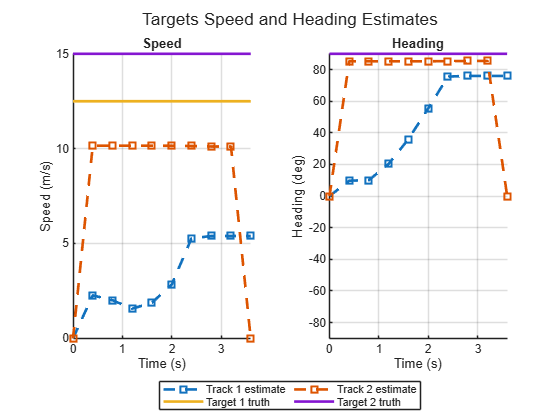


%% Target Speed and Heading Estimation
helperPlotSpeedEstimationResults(t, targets.Trajectories, targetStateEstimates, trackIDs);

Function of targets speed and heading

%% ISAC Scenario and CFAR Frame-by-Frame Visualization
%% Target Speed and Heading Estimation
helperPlotSpeedEstimationResults(t, targets.Trajectories, targetStateEstimates, trackIDs);


%% Metrics summary

% Total number of unique Track IDs created during the simulation.
% Since the scenario contains two moving targets, more than two Track IDs may indicate false tracks or track fragmentation.
totalTrackIDs = numel(trackIDs);

% Summary metrics for topology comparison.
meanNumDetections = mean(numDetectionsPerFrame);
meanNumRawCFARDetections = mean(numRawCFARDetectionsPerFrame);
meanNumTracks = mean(numTracksPerFrame);
totalFalseTracks = sum(falseTracksPerFrame);
meanFalseTracksPerFrame = mean(falseTracksPerFrame);
meanTruthHitRate = mean(truthHitRatePerFrame, "omitnan");
targetTruthHitRate = mean(targetHitMatrix, 1);

% Tracking metrics including all frames.
targetTrackHitRate = mean(trackHitMatrix, 1);
meanTrackHitRate = mean(targetTrackHitRate, "omitnan");
meanTrackPositionError = mean(trackPositionErrorPerFrame, 1, "omitnan");

% Tracking metrics excluding the first frame, because the tracker usually
% needs one frame to initialize/confirm tracks.
trackEvalFrames = 2:numSensingFrames;

targetTrackHitRateNoInit = mean(trackHitMatrix(trackEvalFrames, :), 1);
meanTrackHitRateNoInit = mean(targetTrackHitRateNoInit, "omitnan");
meanTrackPositionErrorNoInit = mean(trackPositionErrorPerFrame(trackEvalFrames, :), 1, "omitnan");

% Temporal alignment diagnostic metrics.
targetTrackHitRatePrevTruth = mean(trackHitPrevTruthMatrix(trackEvalFrames, :), 1);
meanTrackHitRatePrevTruth = mean(targetTrackHitRatePrevTruth, "omitnan");
meanTrackPositionErrorPrevTruth = mean(trackPositionErrorPrevTruthPerFrame(trackEvalFrames, :), 1, "omitnan");

disp("Track position error per frame:");

Track position error per frame:


disp(trackPositionErrorPerFrame);

       NaN       NaN
    1.4807    3.5534
    3.1454    5.5245
    2.5051    7.5004
    4.2224    9.4782
    5.3959   11.4602
    1.9777   13.4613
    4.8084   15.5009
    7.7581   17.4931
   10.7093   27.0636




disp("Track hit matrix:");

Track hit matrix:


disp(trackHitMatrix);

   0   0
   1   1
   1   1
   1   1
   1   0
   1   0
   1   0
   1   0
   1   0
   0   0



disp("Track position error compared with previous-frame truth:");

Track position error compared with previous-frame truth:


disp(trackPositionErrorPrevTruthPerFrame);

       NaN       NaN
    6.4801    2.4570
    2.0657    0.7123
    2.5197    1.6796
    0.9598    3.6025
    1.0077    5.5685
    3.1607    7.5594
    1.1466    9.5890
    3.0534   11.5791
    5.8961   24.3829




disp("Track hit matrix compared with previous-frame truth:");

Track hit matrix compared with previous-frame truth:


disp(trackHitPrevTruthMatrix);

   0   0
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   0
   1   0
   1   0



disp("Detection-level target hit matrix:");

Detection-level target hit matrix:


disp(targetHitMatrix);

   1   1
   1   1
   1   0
   1   0
   1   0
   1   0
   1   0
   1   0
   0   0
   0   0




if numTargets == 2
    disp("Truth range separation per frame:");
    disp(truthRangeSeparationPerFrame);

    disp("Truth AoA separation per frame:");
    disp(truthAoASeparationPerFrame);
end

Truth range separation per frame:


   24.4235
   21.7992
   20.1421
   19.2282
   18.9056
   19.0896
   19.7495
   20.8966
   22.5728
   24.8326



Truth AoA separation per frame:


   17.8189
   19.2108
   20.8040
   22.6337
   24.7376
   27.1497
   29.8849
   32.9052
   36.0463
   38.8678



results.topology = cfg.topology;
results.numDetectionsPerFrame = numDetectionsPerFrame;
results.numRawCFARDetectionsPerFrame = numRawCFARDetectionsPerFrame;
results.meanNumRawCFARDetections = meanNumRawCFARDetections;
results.numTracksPerFrame = numTracksPerFrame;
results.falseTracksPerFrame = falseTracksPerFrame;
results.trackIDs = trackIDs;
results.totalTrackIDs = totalTrackIDs;
results.meanNumDetections = meanNumDetections;
results.meanNumTracks = meanNumTracks;
results.totalFalseTracks = totalFalseTracks;
results.meanFalseTracksPerFrame = meanFalseTracksPerFrame;
results.scenarioName = cfg.scenarioName;
results.targetCase = cfg.targetCase;
results.scenarioDescription = scenarioConfig.description;
% Truth association metrics
results.truthRangeAoAPerFrame = truthRangeAoAPerFrame;
results.clusteredDetectionsPerFrame = clusteredDetectionsPerFrame;
results.truthHitRatePerFrame = truthHitRatePerFrame;
results.meanTruthHitRate = meanTruthHitRate;
results.truthRangeTolerance = truthRangeTolerance;
results.truthAoATolerance = truthAoATolerance;
targetTruthHitRate = mean(targetHitMatrix, 1);
results.trackPositionErrorPerFrame = trackPositionErrorPerFrame;
results.trackHitMatrix = trackHitMatrix;
results.targetTrackHitRate = targetTrackHitRate;
results.meanTrackHitRate = meanTrackHitRate;
results.meanTrackPositionError = meanTrackPositionError;
results.targetHitMatrix = targetHitMatrix;
results.truthRangeSeparationPerFrame = truthRangeSeparationPerFrame;
results.truthAoASeparationPerFrame = truthAoASeparationPerFrame;
results.targetCase = cfg.targetCase;
results.trackDistanceTolerance = trackDistanceTolerance;
results.targetTrackHitRateNoInit = targetTrackHitRateNoInit;
results.meanTrackHitRateNoInit = meanTrackHitRateNoInit;
results.meanTrackPositionErrorNoInit = meanTrackPositionErrorNoInit;
results.targetPositionsHistory = targetPositionsHistory;
results.trackPositionErrorPrevTruthPerFrame = trackPositionErrorPrevTruthPerFrame;
results.trackHitPrevTruthMatrix = trackHitPrevTruthMatrix;
results.targetTrackHitRatePrevTruth = targetTrackHitRatePrevTruth;
results.meanTrackHitRatePrevTruth = meanTrackHitRatePrevTruth;
results.meanTrackPositionErrorPrevTruth = meanTrackPositionErrorPrevTruth;

if cfg.printMetricsSummary
    fprintf('\nBasic ISAC topology metrics summary\n');
    fprintf('Topology: %s\n', cfg.topology);
    if isfield(cfg, "targetCase")
        fprintf('Target case: %s\n', cfg.targetCase);
    end
    fprintf('Mean detections per frame: %.2f\n', meanNumDetections);
    fprintf('Mean raw CFAR detections per frame: %.2f\n', meanNumRawCFARDetections);
    fprintf('Mean tracks per frame: %.2f\n', meanNumTracks);
    fprintf('Total unique Track IDs: %d\n', totalTrackIDs);
    fprintf('Total approximate extra tracks: %d\n', totalFalseTracks);
    fprintf('Mean approximate extra tracks per frame: %.2f\n', meanFalseTracksPerFrame);
    fprintf('Mean truth hit rate: %.2f %%\n', 100 * meanTruthHitRate);
    for it = 1:numTargets
        fprintf('Target %d truth hit rate: %.2f %%\n', it, 100 * targetTruthHitRate(it));
    end
    fprintf('Truth association tolerances: %.2f m, %.2f deg\n', ...
        truthRangeTolerance, truthAoATolerance);
    fprintf('Scenario: %s\n', cfg.scenarioName);
    fprintf('Mean track hit rate: %.2f %%\n', 100 * meanTrackHitRate);

    for it = 1:numTargets
        fprintf('Target %d track hit rate: %.2f %% | mean track error: %.2f m\n', ...
            it, ...
            100 * targetTrackHitRate(it), ...
            meanTrackPositionError(it));
    end
    fprintf('Mean track hit rate excluding first frame: %.2f %%\n', ...
        100 * meanTrackHitRateNoInit);
    fprintf('Mean track hit rate compared with previous-frame truth: %.2f %%\n', ...
        100 * meanTrackHitRatePrevTruth);

    for it = 1:numTargets
        fprintf('Target %d track hit rate vs previous-frame truth: %.2f %% | mean error vs previous-frame truth: %.2f m\n', ...
            it, ...
            100 * targetTrackHitRatePrevTruth(it), ...
            meanTrackPositionErrorPrevTruth(it));
    end
    for it = 1:numTargets
        fprintf('Target %d track hit rate excluding first frame: %.2f %% | mean track error excluding first frame: %.2f m\n', ...
            it, ...
            100 * targetTrackHitRateNoInit(it), ...
            meanTrackPositionErrorNoInit(it));
    end
end


Basic ISAC topology metrics summary


Topology: bistatic


Target case: twoTargetsOriginalFast


Mean detections per frame: 1.00


Mean raw CFAR detections per frame: 21.70


Mean tracks per frame: 1.70


Total unique Track IDs: 2


Total approximate extra tracks: 0


Mean approximate extra tracks per frame: 0.00


Mean truth hit rate: 50.00 %


Target 1 truth hit rate: 80.00 %
Target 2 truth hit rate: 20.00 %


Truth association tolerances: 8.00 m, 10.00 deg


Scenario: piotrkowskaStreetCanyon


Mean track hit rate: 55.00 %


Target 1 track hit rate: 80.00 % | mean track error: 4.67 m
Target 2 track hit rate: 30.00 % | mean track error: 12.34 m


Mean track hit rate excluding first frame: 61.11 %


Mean track hit rate compared with previous-frame truth: 83.33 %


Target 1 track hit rate vs previous-frame truth: 100.00 % | mean error vs previous-frame truth: 2.92 m
Target 2 track hit rate vs previous-frame truth: 66.67 % | mean error vs previous-frame truth: 7.46 m


Target 1 track hit rate excluding first frame: 88.89 % | mean track error excluding first frame: 4.67 m
Target 2 track hit rate excluding first frame: 33.33 % | mean track error excluding first frame: 12.34 m


Supporting Functions

function tracker = helperConfigureTrackerByTopology(topology, txPosition, rxPosition, txOrientation, rxOrientation, rangeResolution, aoaResolution)
if topology == "bistatic"
    sensorSpec = trackerSensorSpec("aerospace", "radar", "bistatic");
    sensorSpec.MeasurementMode = "range-angle";
    sensorSpec.IsReceiverStationary = true;
    sensorSpec.IsEmitterStationary = true;
    sensorSpec.HasElevation = false;
    sensorSpec.HasRangeRate = false;
    sensorSpec.MaxNumLooksPerUpdate = 1;
    sensorSpec.MaxNumMeasurementsPerUpdate = 10;
    sensorSpec.EmitterPlatformPosition = txPosition;
    sensorSpec.EmitterPlatformOrientation = txOrientation.';
    sensorSpec.ReceiverPlatformPosition = rxPosition;
    sensorSpec.ReceiverPlatformOrientation = rxOrientation.';
    sensorSpec.RangeResolution = rangeResolution;
    sensorSpec.AzimuthResolution = aoaResolution;
    sensorSpec.ReceiverFieldOfView = [360 180];
    sensorSpec.EmitterFieldOfView = [360 180];
    sensorSpec.ReceiverRangeLimits = [0 500];
    sensorSpec.EmitterRangeLimits = [0 500];
    sensorSpec.DetectionProbability = 0.9;
else
    sensorSpec = trackerSensorSpec("aerospace", "radar", "monostatic");
    sensorSpec.PlatformPosition = rxPosition;
    sensorSpec.PlatformOrientation = rxOrientation.';
    sensorSpec.RangeResolution = rangeResolution;
    sensorSpec.AzimuthResolution = aoaResolution;
    sensorSpec.DetectionProbability = 0.9;
end

targetSpec = trackerTargetSpec('custom');
targetSpec.StateTransitionModel = targetStateTransitionModel('constant-velocity');
targetSpec.StateTransitionModel.NumMotionDimensions = 2;
targetSpec.StateTransitionModel.VelocityVariance = 15^2/3*eye(2);
targetSpec.StateTransitionModel.AccelerationVariance = 0.01^2/3*eye(2);
tracker = multiSensorTargetTracker(targetSpec, sensorSpec, "jipda");
tracker.ConfirmationExistenceProbability = 0.98;
tracker.MaxMahalanobisDistance = 10;
end

function detections = helperFormatDetectionsForTrackerByTopology(topology, clusteredDetections, currentTime, rangeResolution, aoaResolution)
if topology == "bistatic"
    detections = helperFormatBistaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution);
else
    detections = helperFormatMonostaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution);
end
end

function detections = helperFormatBistaticDetectionsForTracker(clusteredDetections, currentTime, rangeResoultion, aoaResolution)
numDetections = size(clusteredDetections, 2);
detections.ReceiverLookTime = currentTime;
detections.ReceiverLookAzimuth = 0;
detections.ReceiverLookElevation = 0;
detections.EmitterLookAzimuth = 0;
detections.EmitterLookElevation = 0;
detections.DetectionTime = ones(1, numDetections) * currentTime;
detections.Azimuth = clusteredDetections(2, :);
detections.Range = clusteredDetections(1, :);
detections.AzimuthAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.RangeAccuracy = ones(1, numDetections) * rangeResoultion/8;
end

function detections = helperFormatMonostaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution)
numDetections = size(clusteredDetections, 2);
detections = struct;
detections.LookTime = currentTime;
detections.LookAzimuth = 0;
detections.LookElevation = 0;
detections.DetectionTime = ones(1, numDetections) * currentTime;
detections.SensorIndex = ones(1, numDetections);
detections.Range = clusteredDetections(1, :);
detections.Azimuth = clusteredDetections(2, :);
detections.Elevation = zeros(1, numDetections);
detections.RangeRate = zeros(1, numDetections);
detections.RangeAccuracy = ones(1, numDetections) * rangeResolution/8;
detections.AzimuthAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.ElevationAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.RangeRateAccuracy = ones(1, numDetections) * 1;
detections.Measurements = [detections.Range; detections.Azimuth; detections.Elevation];
detections.MeasurementParameters = repmat(struct(), 1, numDetections);
end

function meascart = helperGetCartesianMeasurement(dets, txPosition, rxPosition, rxOrientationAxes)
if ~isempty(dets)
    n = size(dets, 2);
    meassph = zeros(3, n);
    meassph(1, :) = dets(2, :);
    meassph(3, :) = dets(1, :);
    meassph = local2globalcoord(meassph, 'ss', [0; 0; 0], rxOrientationAxes);
    meascart = bistaticposest(meassph(3, :), meassph(1:2, :), eps*ones(1, n), repmat([eps; eps], 1, n),...
        txPosition, rxPosition, 'RangeMeasurement', 'BistaticRange');
else
    meascart = [];
end
end

function meascart = helperGetMonostaticCartesianMeasurement(dets, rxPosition, rxOrientationAxes)
if ~isempty(dets)
    r = dets(1, :);
    az = dets(2, :);
    xLocal = r .* cosd(az);
    yLocal = r .* sind(az);
    zLocal = zeros(size(r));
    meascartLocal = [xLocal; yLocal; zLocal];
    meascart = rxPosition + rxOrientationAxes * meascartLocal;
else
    meascart = [];
end
end

function trajectories = helperGetTargetTrajectories(scenarioName, targetCase)
% helperGetTargetTrajectories
% Defines target trajectories depending on the selected scenario and target case.

    if nargin < 1
        scenarioName = "baseline";
    end

    if nargin < 2
        targetCase = "default";
    end

    switch scenarioName

        case "baseline"

            timeOfArrival = [0 4];

            waypoints1 = [25 -5 0;
                          40 30 0];

            waypoints2 = [70 30 0;
                          80 10 0];

            traj1 = waypointTrajectory(waypoints1, timeOfArrival);
            traj2 = waypointTrajectory(waypoints2, timeOfArrival);

            trajectories = {traj1, traj2};

        case "openArea"

            timeOfArrival = [0 4];

            waypoints1 = [-105 -50 0;
                           -45  10 0];

            waypoints2 = [-95  20 0;
                          -35 -45 0];

            traj1 = waypointTrajectory(waypoints1, timeOfArrival);
            traj2 = waypointTrajectory(waypoints2, timeOfArrival);

            trajectories = {traj1, traj2};

        case "piotrkowskaStreetCanyon"

            switch targetCase

                case "singleT1Fast"

                    timeOfArrival = [0 4];

                    waypoints1 = [-10 -25 0;
                                  -10  25 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    trajectories = {traj1};

                case "singleT1Slow"

                    timeOfArrival = [0 8];

                    waypoints1 = [-10 -25 0;
                                  -10  25 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    trajectories = {traj1};

                case "singleT2Slow"

                    timeOfArrival = [0 8];

                    waypoints1 = [15 -30 0;
                                  15  30 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    trajectories = {traj1};

                case "twoTargetsOriginalFast"

                    timeOfArrival = [0 4];

                    waypoints1 = [-10 -25 0;
                                  -10  25 0];

                    waypoints2 = [15 -30 0;
                                  15  30 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    traj2 = waypointTrajectory(waypoints2, timeOfArrival);

                    trajectories = {traj1, traj2};

                case "twoTargetsOriginalSlow"

                    timeOfArrival = [0 8];

                    waypoints1 = [-10 -25 0;
                                  -10  25 0];

                    waypoints2 = [15 -30 0;
                                  15  30 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    traj2 = waypointTrajectory(waypoints2, timeOfArrival);

                    trajectories = {traj1, traj2};

                case "twoTargetsSeparatedSlow"

                    timeOfArrival = [0 8];

                    % More laterally separated two-target case.
                    % This tests whether the degradation observed in the original
                    % two-target case is caused by insufficient range-AoA separability.
                    waypoints1 = [-20 -25 0;
                                  -20  25 0];

                    waypoints2 = [15 -30 0;
                                  15  30 0];

                    traj1 = waypointTrajectory(waypoints1, timeOfArrival);
                    traj2 = waypointTrajectory(waypoints2, timeOfArrival);

                    trajectories = {traj1, traj2};

                otherwise
                    error("Unknown targetCase for piotrkowskaStreetCanyon: %s", targetCase);
            end

        otherwise
            error("Unknown scenarioName: %s", scenarioName);
    end
end

function helperPlotSpeedEstimationResults(t, trajectories, targetStateEstimates, trackIDs)
    fig = figure;
    tl = tiledlayout(fig, 1, 2);
    speedAxes = nexttile(tl);
    hold(speedAxes, 'on');
    
    xlabel(speedAxes, 'Time (s)');
    ylabel(speedAxes, 'Speed (m/s)');
    grid(speedAxes, 'on');
    title(speedAxes, 'Speed');
    xlim(speedAxes, [t(1) t(end)]);
    lgd = legend(speedAxes, 'Location', 'southeast', 'Orientation', 'horizontal', 'NumColumns', 2);
    lgd.Layout.Tile = 'south';
    
    headingAxes = nexttile(tl);
    hold(headingAxes, 'on');
    xlabel(headingAxes, 'Time (s)');
    ylabel(headingAxes, 'Heading (deg)');
    grid(headingAxes, 'on');
    title(headingAxes, 'Heading');
    ylim(headingAxes, [-90 90]);    
    xlim(headingAxes, [t(1) t(end)]);

    sgtitle(fig, 'Targets Speed and Heading Estimates')
    
    for it = 1:numel(trackIDs)
        id = trackIDs(it);
        vx = targetStateEstimates(2, :, id);
        vy = targetStateEstimates(4, :, id);
    
        speedEstimate = sqrt(vx.^2 + vy.^2);
        headingEstimate = atan2d(vy, vx);
        plot(speedAxes, t, speedEstimate, 's--', 'LineWidth', 2, 'DisplayName', sprintf('Track %d estimate', trackIDs(it)));
        plot(headingAxes, t, headingEstimate, 's--', 'LineWidth', 2);
    end
    
    for it = 1:numel(trajectories)
        [~, ~, velocity] = lookupPose(trajectories{it}, t);
        trueSpeed = sqrt(velocity(:, 1).^2 + velocity(:, 2).^2);
        trueHeading = atan2d(velocity(:, 2), velocity(:, 1));
        
        plot(speedAxes, t, trueSpeed, '-', 'LineWidth', 2, 'DisplayName', sprintf('Target %d truth', it));
        plot(headingAxes, t, trueHeading, '-', 'LineWidth', 2);
    end
end

helper scenario

function scenarioConfig = helperGetScenarioConfig(scenarioName, topology)
% helperGetScenarioConfig
% Defines scenario-dependent geometry, scatterer source and array orientation.

scenarioConfig = struct();
scenarioConfig.name = scenarioName;
scenarioConfig.topology = topology;

switch scenarioName

    case "baseline"

        scenarioConfig.description = "Controlled baseline scenario with randomly generated scatterers";
        scenarioConfig.useOSMScatterers = false;
        scenarioConfig.scattererMatFile = "";

        scenarioConfig.roi = [0 120;
                             -80 80];

        txPosition = [0; 0; 0];

        % Keep original baseline orientations.
        txOrientationAxes = eye(3);

        switch topology
            case "monostatic"
                rxPosition = txPosition;
                rxOrientationAxes = txOrientationAxes;

            case "bistatic"
                rxPosition = [50; 60; 0];
                rxOrientationAxes = rotz(-90);

            otherwise
                error('topology must be "monostatic" or "bistatic".');
        end

    case "openArea"

        scenarioConfig.description = "OSM-based UMi open-area scenario";
        scenarioConfig.useOSMScatterers = true;
        scenarioConfig.scattererMatFile = "open_area_osm_scatterers.mat";

        scenarioConfig.roi = [-120 -20;
                               -70  30];

        txPosition = [-100; -60; 0];

        % Look roughly towards the centre of the target/ROI area.
        lookPoint = [-70; -20; 0];

        txOrientationAxes = helperLookAt2D(txPosition, lookPoint);

        switch topology
            case "monostatic"
                rxPosition = txPosition;
                rxOrientationAxes = txOrientationAxes;

            case "bistatic"
                rxPosition = [-30; 0; 0];
                rxOrientationAxes = helperLookAt2D(rxPosition, lookPoint);

            otherwise
                error('topology must be "monostatic" or "bistatic".');
        end

    case "piotrkowskaStreetCanyon"

        scenarioConfig.description = "OSM-based UMi street-canyon scenario";
        scenarioConfig.useOSMScatterers = true;
        scenarioConfig.scattererMatFile = "piotrkowska_osm_scatterers.mat";

        scenarioConfig.roi = [-50 50;
                              -50 50];

        txPosition = [-10; -40; 0];

        % Street canyon along y direction.
        txLookPoint = [-10; 0; 0];
        txOrientationAxes = helperLookAt2D(txPosition, txLookPoint);

        switch topology
            case "monostatic"
                rxPosition = txPosition;
                rxOrientationAxes = txOrientationAxes;

            case "bistatic"
               %Case original
                rxPosition = [-20; 40; 0];
                rxLookPoint = [-10; 0; 0];
                %Caso RX-C: Rx desplazado hacia Target 2    
                %rxPosition = [20; 40; 0];
                %rxLookPoint = [15; 0; 0];
                %Caso RX-B: Rx centrado, mirando al centro
                %rxPosition = [0; 40; 0];
                %rxLookPoint = [0; 0; 0];
                %Caso RX-A: misma posición, mirando a Target 2
                %rxLookPoint = [15; 0; 0];
                %rxPosition = [-20; 40; 0];
                %original
                %rxLookPoint = [-10; 0; 0];
                %rxPosition = [-20; 40; 0];
                rxOrientationAxes = helperLookAt2D(rxPosition, rxLookPoint);

            otherwise
                error('topology must be "monostatic" or "bistatic".');
        end

    otherwise
        error("Unknown scenarioName: %s", scenarioName);
end

scenarioConfig.txPosition = txPosition;
scenarioConfig.rxPosition = rxPosition;
scenarioConfig.txOrientationAxes = txOrientationAxes;
scenarioConfig.rxOrientationAxes = rxOrientationAxes;

end

other

function orientationAxes = helperLookAt2D(position, lookPoint)
% helperLookAt2D
% Returns a yaw-only orientation matrix whose local x-axis points
% approximately from position to lookPoint in the x-y plane.

direction = lookPoint - position;
yawDeg = atan2d(direction(2), direction(1));
orientationAxes = rotz(yawDeg);

end

Frame Truth Hit Run 

function [frameTruthHitRate, targetHits] = helperComputeFrameTruthHitRate(truthRangeAoA, clusteredDetections, rangeTolerance, aoaTolerance)
% helperComputeFrameTruthHitRate
% Computes the fraction of real targets that have at least one clustered
% detection close to them in the range-AoA map.
%
% Outputs:
%   frameTruthHitRate : fraction of targets detected in this frame
%   targetHits        : 1 x numTargets logical vector

numTargets = size(truthRangeAoA, 2);
targetHits = false(1, numTargets);

if numTargets == 0
    frameTruthHitRate = NaN;
    return;
end

if isempty(clusteredDetections)
    frameTruthHitRate = 0;
    return;
end

for targetIdx = 1:numTargets

    trueRange = truthRangeAoA(1, targetIdx);
    trueAoA = truthRangeAoA(2, targetIdx);

    detectedRange = clusteredDetections(1, :);
    detectedAoA = clusteredDetections(2, :);

    rangeError = abs(detectedRange - trueRange);
    aoaError = abs(wrapTo180(detectedAoA - trueAoA));

    normalizedDistance = sqrt( ...
        (rangeError ./ rangeTolerance).^2 + ...
        (aoaError ./ aoaTolerance).^2);

    targetHits(targetIdx) = any(normalizedDistance <= 1);
end

frameTruthHitRate = mean(targetHits);

end

Track truth error

function [targetErrors, targetTrackHits] = helperComputeTrackTruthError(tracks, targetPositions, distanceTolerance)
% helperComputeTrackTruthError
% Computes the Cartesian distance between each true target and the closest
% active track.
%
% Inputs:
%   tracks             - tracker output
%   targetPositions    - numTargets x 3 matrix with true target positions
%   distanceTolerance  - maximum distance for considering a track close
%
% Outputs:
%   targetErrors       - 1 x numTargets minimum distance to any track
%   targetTrackHits    - 1 x numTargets logical vector

numTargets = size(targetPositions, 1);
targetErrors = NaN(1, numTargets);
targetTrackHits = false(1, numTargets);

if isempty(tracks)
    return;
end

numTracks = numel(tracks);
trackPositions = NaN(numTracks, 2);

for k = 1:numTracks
    state = tracks(k).State;

    % Current tracker state convention:
    % State = [x; vx; y; vy]
    trackPositions(k, :) = [state(1), state(3)];
end

for targetIdx = 1:numTargets

    trueXY = targetPositions(targetIdx, 1:2);

    distances = vecnorm(trackPositions - trueXY, 2, 2);

    targetErrors(targetIdx) = min(distances);
    targetTrackHits(targetIdx) = targetErrors(targetIdx) <= distanceTolerance;
end

end
